Sentencia Switch 

Básicamente, nos separa por casos según los valores que pueda asumir una variable. Ahora, si encuentra que uno de los casos se cumple, ya no sigue revisando los demás casos. 

Ejemplo 1: 

*Discusión*: 

Ejemplo 2: 

Dado un vector x = [1 4 6 4.5 8 2.5 8], defina una opción para el tipo de gráfica que quiere usar para representar estos datos. Las opciones serán: bar, barh, bar3, pie, pie3. Sin embargo, para la opción de barh y bar3 use siempre para graficar a bar3.

x = [1 4 6 4.5 8 2.5 8];
clc
disp(['Determine cuál de los tipos de barras es el que quiere para presentar los datos: \n' ...
    'bar, barh, bar3, pie, pie3 ' ...
    'si determina la opción barh o bar3, le saldrá bar3' ]);

Determine cuál de los tipos de barras es el que quiere para presentar los datos: \nbar, barh, bar3, pie, pie3 si determina la opción barh o bar3, le saldrá bar3


prompt='El tipo que quiere es: ';
tipoplot= input(prompt, 's');
if isempty(tipoplot)
    tipoplot='bar';
end
switch tipoplot 
    case 'bar'
        bar(x);
        disp('Gráfico de barras estándar ');
    case {'barh', 'bar3'}
        bar3(x);
        disp('Gráfico de barras en 3D');
    case 'pie'
        pie(x);
        disp('Gráfico de torta estándar');
    case 'pie3'
        pie3(x);
        disp('Gráfico de torta 3D');
    otherwise
        warning('Tipo no válido.')
end

Gráfico de barras estándar 


Comando MENU 

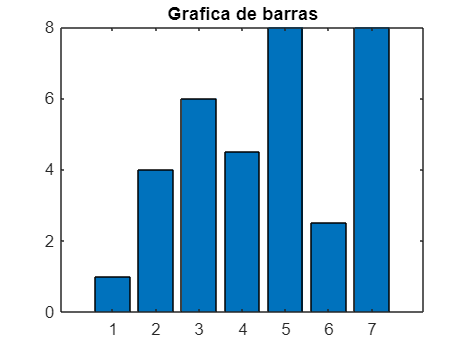

x = [1 4 6 4.5 8 2.5 8];
clc
tipoplot = menu('Escriba la opción de tu preferencia: ','Graficar con bar','Graficar con barh',...
'Graficar con bar3', 'Graficar con pie', 'Graficar con pie3' );
if isempty(tipoplot)
tipoplot = 'pie';
end
switch tipoplot
case 1
bar(x)
title('Grafica de barras')
case {2,3}
bar3(x)
title('Grafica de barras tridimensional')
case 4,
pie(x)
title('Gráfica de pastel tridimensional')
case 5,
pie3(x)
title('Gráfica de pastel tridimensional')
otherwise
warning('Indefinida tipo de gráfica. No se ha creado plot')
end

**Comandos BREAK y CONTINUE **

Break sirve para salirse completamente de un bucle (se sale del más pequeño en el que se ponga el break. 

Continue lo que hace es que si hace que el bucle más pequeño salte al siguiente valor. 

Ejemplo: con break 

n = 0;
while n < 10,
n = n+1;
a = input('Ingrese un valor mayor que 0: ');
if a <=0,
disp('Debe ingresar un número positivo');
disp('Este programa terminará');
break;
end
disp('El logaritmo natural de este número es ');
disp(log(a));
end

El logaritmo natural de este número es 


    1.3863



El logaritmo natural de este número es 


    0.6931



El logaritmo natural de este número es 


    1.0986



El logaritmo natural de este número es 


    1.3863



El logaritmo natural de este número es 


    1.6094



El logaritmo natural de este número es 


    1.7918



El logaritmo natural de este número es 


    1.9459



El logaritmo natural de este número es 


    2.0794



Debe ingresar un número positivo


Este programa terminará


Ejemplo con continue 

n = 0;
while n<10,
n = n+1;
a = input('Ingrese un valor mayor que 0: ');
if a <=0,
disp('Debe ingresar un número positivo');
disp('Intente de nuevo');
continue;
end
disp('El logaritmo natural de este número es ');
disp(log(a));
end

El logaritmo natural de este número es 


     0



El logaritmo natural de este número es 


    0.6931



El logaritmo natural de este número es 


    1.0986



El logaritmo natural de este número es 


    1.3863



El logaritmo natural de este número es 


    1.6094



Debe ingresar un número positivo


Intente de nuevo


El logaritmo natural de este número es 


    1.9459



El logaritmo natural de este número es 


    2.0794



El logaritmo natural de este número es 


    2.1972



El logaritmo natural de este número es 


    2.3026



Funciones con matlab 

r = input('Introduzca el radio del cilindro: ');
h = input('Intruduzca la altura: ');
[a,v] = cilindro(r,h);
disp(['El área es: ', num2str(a)])

El área es: 131.9469


disp(['El volumen es: ', num2str(v)])

El volumen es: 113.0973



% Ejercicio 1 Raices de la ecuacion cuadratica:
a = input('Ingrese el valor del número a ');
b = input('Ingrese el valor del número b ');
c = input('Ingrese el valor del número c ');
[x1,x2] = RaizCuadrada(a,b,c);

Las raices son complejas


Output argument "x1" (and possibly others) not assigned a value in the execution with "RaizCuadrada" function.

disp(['La primera raíz es: ', num2str(x1)]);
disp(['La segunda raíz es: ', num2str(x2)]);

Nota: 

**clc** se usa para limpiar la 'Command window'

**clear** si es para limpiar la memoria

**disp** es para mostrar texto en la pantalla al usuario. 

**prompt** se utiliza para presentarle texto al usuario, usualmente es la orden de que introduzca los datos. Con este se crea un vector de caracteres que es el que aparece en pantalla. Este comando sirve para pedir datos de distinto tipo. Por ejemplo, al utilizar `tipoplot = input(prompt,'s') `se muestra el texto asignado en el vector prompt, reconociendo que debe ser tipo texto (para que quede guardado en la variable, de lo contrario quedará vacía). 

**input** es para 